% b = [0.3, 1, 0.3];  % 分子系数
% a = 1;  % 分母系数
% a1=1;
% b1=[0.3 -1 0.3];
% [h1,w1]=freqz(b1,a1);
% [h, w] = freqz(b, a);  % 计算频率响应
% 
% magnitude = abs(h);  % 幅度响应
% phase = angle(h);  % 相位响应
% figure;
% subplot(2, 1, 1);
% plot(w/pi, magnitude);
% hold on 
% plot(w1/pi,abs(h1))
% hold off
% xlim([0,1])
% grid minor
% title('Magnitud Response');
% xlabel('\omega/\pi');
% ylabel('Magnitude');
% legend('Filter hA', 'Filter hB');
% % 绘制相位响应
% subplot(2, 1, 2);
% plot(w/pi, phase);
% hold on
% plot(w1/pi,angle(h1))
% xlim([0,1])
% ylim([-pi,pi])
% grid minor
% title('Phase Response');
% xlabel('\omega/\pi');
% ylabel('Phase');
% legend('Filter hA', 'Filter hB');




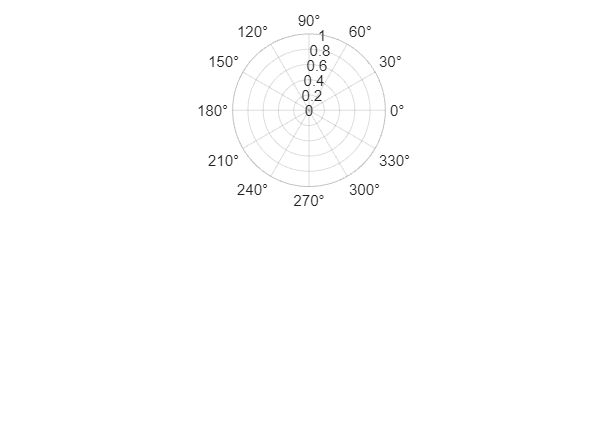

数据的维度不能超过二维。

% Define the transfer function H(s)
num = 1;
den = [1 pi];

% Create a transfer function object
H = tf(num, den);

% Define the frequency range
w = logspace(-2, 2, 1000); % Frequency range from 0.01 to 100

% Evaluate the transfer function at the given frequencies
Hw = freqresp(H, w);

% Convert to magnitude and phase
magnitude = abs(Hw);
phase = angle(Hw);

% Convert phase to degrees
phase_deg = rad2deg(phase);

% Plot the magnitude and phase response
figure;
subplot(2, 1, 1);
polarplot(phase, magnitude);

title('Magnitude Response');
subplot(2, 1, 2);
polarplot(phase, phase_deg);
title('Phase Response');
